# Simulation of LPNN in LASSO problem

We are concerned about the **LASSO constrained problem** that may be expressed as follows:

$\underset{x}{\;\min } \;{\left\|r-\phi x\right\|}_2^2 \;,$ s.t. ${\left\|x\right\|}_1  \le \eta$

In this simulation, we try to investigate the LPNN approach (Lagrange Programming Neural Network) on a singal processing area. Let's formulate the problem in a such way it make it clearer.

## Problem foundation

In compressive sampling, we receive a noisy observation $r=\phi \;x+\xi \in  R^m$ where

- $\phi \;\in R^{m\times n} \;$  is the measurement matrix, with $m<n$

- $x\in R^n$ is the original signal

- $\xi \in R^m$ is the noise vector

Recovering the unknown original vector $x$ is considering the **LASSO** problem 

$\underset{x}{\;\min } \;{\left\|r-\phi x\right\|}_2^2 \;,$ s.t. ${\left\|x\right\|}_1  \le \eta$

In our study we readjust the previous formulation as follows

$\underset{x}{\;\min } \;{\left\|r-\phi x\right\|}_2^2 \;,$ s.t. ${\left\|x\right\|}_{1,k}  \le \eta$

where  ${\left\| x\right\|}_{1,k} =\sum_{i=1}^n {\left|x_i \right|}_{1,k}$where  ${\left|x_i \right|}_{1,k} =\frac{1}{k}\left\lbrack \ln \left(1+e^{-{\textrm{kx}}_i  } \right)+\ln \left(1+e^{{\textrm{kx}}_i } \right)\right\rbrack$

## Experiments

In this part, we generate a compressive sampling vector $x$ having $n$ components with $N_z$ nonzeros ones. We derive from it a corresponding observation $r$ by adding some noise $\xi$ according to the Gaussian distribution. We try to figure out the original signal $x$ from that observation $r$. And hence we could evaluate the performance of the recovering method with the MSE. The details follow Section 5 of [1] description. And this can be summarized as follows

- $n=512$ with $N_z =15,20,25$ and $n=4096$ with $N_z =\;75,100,125$

- Nonzero components' values are -1 or 1

- Random $\pm 1$ matrix is used as measurement matrix $\phi$. Each column must be normalized.

- The noise level are $\sigma^2 =0\ldotp {02}^2 ,0\ldotp {01}^2 ,0\ldotp {001}^2$

- Each setting is simulated 100 times and the results are then reported.

## Coding

Setting up the workspace

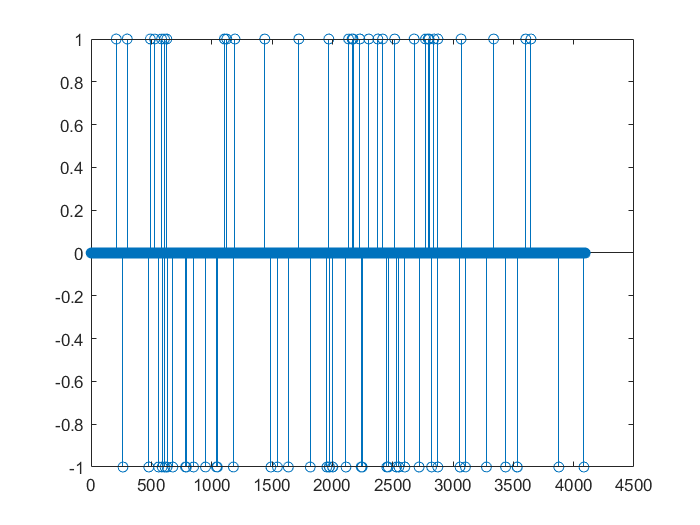

clear variables;
clc;
% Initialisations

rng('shuffle');     % Force the same random number generation
m = 100;            % Number of measurements
sigma = 0.02;       % Noise power level
% Generating the sampling vector
% Recall that $x\in R^n$ having $N_z$ nnz components with an amplitude $\pm 
% 1$ and $\left|x{\left|\right.}_1 <\eta \right.$.

n = 4096;            % Signal length
Nz = 75;            % The number of nnz
amplitude = 1;      % Signal amplitude
eta = amplitude * Nz;

% Code Anis
x = zeros(n,1);
q = randperm(n);
x(q(1:Nz)) = (amplitude+1)*ones(Nz,1);
iter=0;
while (norm(x,1)>eta)
      x(q(1:Nz)) = amplitude*sign(randn(Nz,1));
      iter=iter+1;
end
% Code Anis

% Check nnz components number
assert(sum(x~=0)==Nz,'There is nnz %d instead of %d.', sum(x~=0), Nz)
% Check vector l1 norm
assert(norm(x,1) <= eta, '|x|=%.2f > %.2f.', norm(x,1), eta)

% Plot the signal
stem(x);

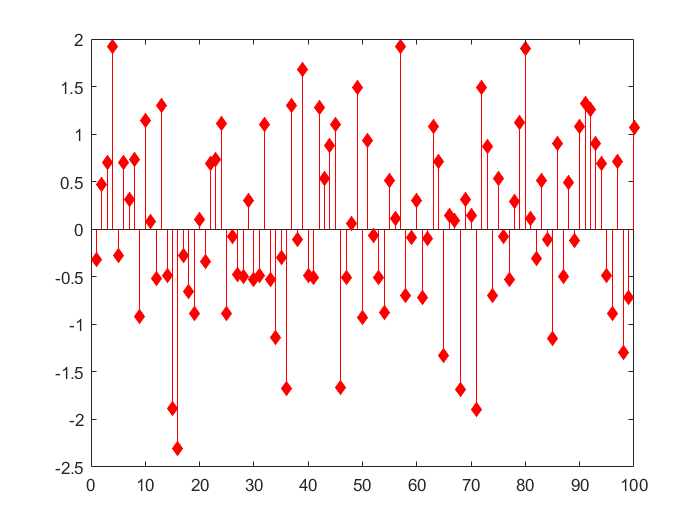

% Generating the measuremnt matrix
% Recall that $\phi \in R^{m\times n}$ matrix with $\pm 1$ components. Each 
% column have to be normilized.

phi = randn(m, n);                      % Generating the matrix
phi = -(phi<0) + (phi>=0);              % +1/-1 values
phi = normc(phi);                       % Column normalization
assert(rank(phi) == m, 'phi is not full rank');
% Generating the observation
% Recall that $r=\phi \;x+\xi$

xi = sigma * randn(m, 1);   % Noisy vector
r = phi * x + xi;           % The observation
% Plot signal
stem(r, 'diamondr', 'filled');

## Solution and performance

We are using ODE solver in our approach. The solver requires initial conditions $x_0$ to start integration. We want to inspect how the initial conditions affect the performance of the solver. Moreover, each solver may impact differently the performance mainly the time execution and the memory usage. We also want to unfold the effect of the solver on the performance. Preliminary experiments show that the execution time may exceeds 10h with more than 5000 iterations in some circumstances, that's why we force the execution to break off when reaching the first 500 iterations.

Initial conditiuon is:

- 
$${\left\|x_0 \right\|}_{1,k} <\eta$$


In our experiments we try evaluate the following scenarios, generate $x_0$ according

- 
$$x_0 =A\times 0\ldotp 03\times N\left(0,1\right)$$


- $x_0 =\beta \ldotp \textrm{xg}$ where $\beta =\frac{0\ldotp 95\times \eta  }{{\left\|x_0 \right\|}_{1,k} }$ and $\textrm{xg}=A\times N\left(0,1\right)$

- 
$$\dots$$


% Select one approach to generate x0
nApproach = 2;
nx0 = 1;
switch nApproach
    case 1
        % 1st approach
        x0 = amplitude * 0.03 * randn(n,nx0);
        %x0(:,nx0) = zeros(n,1);
    case 2
        % 2nd approach
        xg = amplitude * randn(n,nx0);
        beta = (0.95 * eta) / norm(xg, 1);
        x0 = beta * xg;
    otherwise
        % 3rd approach
        % to be implemented
end
%stem(x0);
%fprintf('end');

% The solver selection
% The used solver is ODE113. Along with different dynamics were tested such 
% as

## Select a method

- pklpnn1: our approach (first impementation)

- pklpnn2: our approach (second impementation)

- pklpnnNew

- lpnn: as described in [1]

- lassoConstrained

- lassoActiveSet

Refer to [https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

% 1: pklpnn v1, 2: pklpnn v2, 3: pklpnnNew 4: lassolpnn, 
% 5: LassoConstrained other: LassoActiveSet
nSolver = 3;
switch(nSolver)
    case 1
        % pk-LPNN v1
        saveFile = 'pkLPNN1';
    case 2
        % pk-LPNN v2
        saveFile = 'pkLPNN2';
    case 3
        % pk-LPNN new
        saveFile = 'pkLPNNNEW';
    case 4
        % LASSO-LPNN
        saveFile = 'lassoLPNN';
    case 5
        % LassoConstrained
        saveFile = 'lassoConsLPNN';
    otherwise
        % LassoActiveSet
        saveFile = 'LassoActiveSetLPNN';
end

## x0

% Just testing the default method in lpnn1 (Mr Anis version)
% Select switch solver

tk = 5000; %3 * 10^8;%

timenomr = zeros(nx0,1);
nDigits = 10;
for i=1:nx0
    tic;
    norx0 = computeNorm(nSolver,x0(:,i),tk);
    timenomr(i) = toc;
    fprintf('||x0%d||k,1=%.4f\n',i,norx0);
    assert(norx0<=eta,'x0 does not comply');
end

||x01||k,1=71.2669


## Solving ODE with function

oldprec = digits(nDigits);
t = [0 150]; %linspace(0,100,10);%
k = 5000;
lamda0 = .5;


setting.eta = eta;
data.x0 = x0;
data.phi = phi;
data.r = r;
data.x = x;
simParam.lambda0 =lamda0;
simParam.tspan = t;
setting.k = k;



%odeSol = cell(1, nx0);

odeSol = odeSolver(data, simParam, setting, nSolver);
fprintf('error = %E time = %s\n',odeSol.odeerr(end),...
    char(duration(0,0,odeSol.timeode)));

error = 1.871512E-02 time = 00:00:00



fprintf('done');

done



digits(oldprec);
saveFile = sprintf('sim-%s-n%dm%dnz%dsg%.0ek%.0gphiUN.mat',...
    saveFile,n,m,Nz,sigma,k);

save(saveFile);